# ECE 345/ME 380: Introduction to Control Systems

## Collaborative Quiz #3

### 1.1 Location of poles and zeros of G(s)

num1=[1]; den1=[1 7 12 0];roots(den1)

ans =      0
    -4
    -3


### 1.3 Step response of the open-loop system

sys1=tf(num1,den1)

sys1 =
 
          1
  ------------------
  s^3 + 7 s^2 + 12 s
 
Continuous-time transfer function.



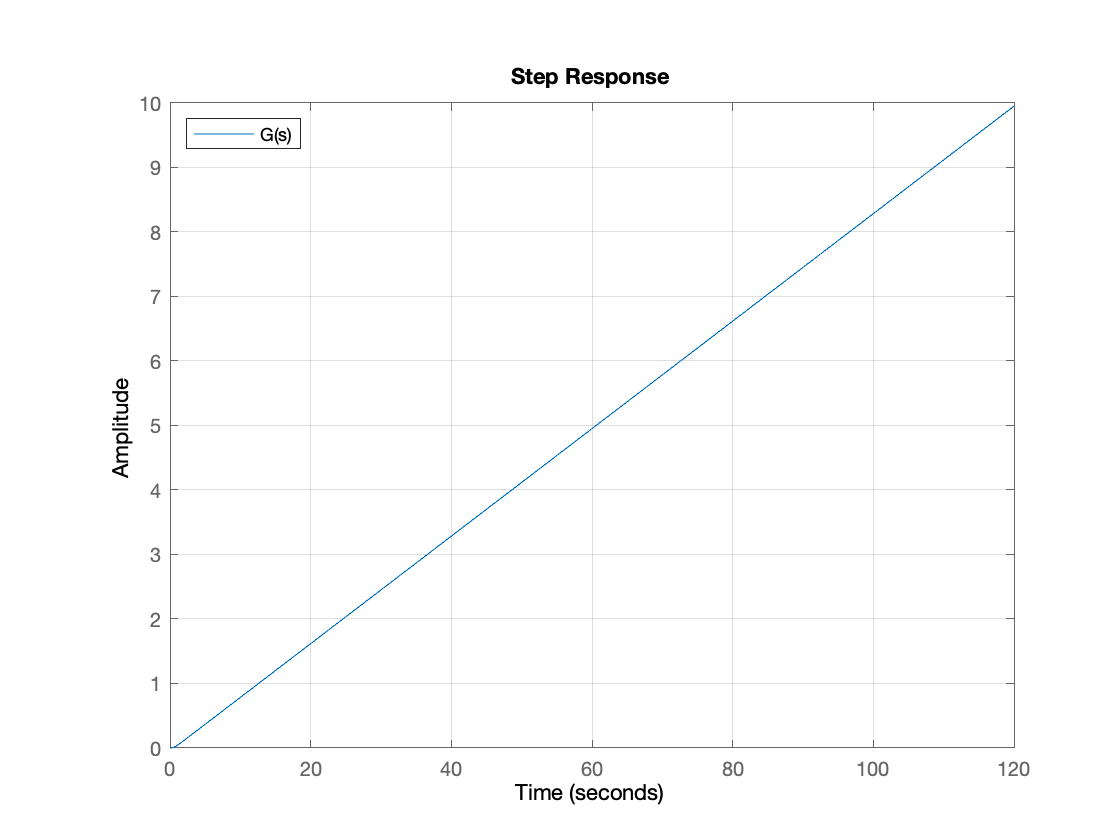

step(sys1);grid;legend('G(s)','location','northwest')

### 2.5 Step response of the closed-loop system with K=100 over 0 to 20

K=100;tfinal=20;
sys2=K*feedback(sys1,K)

sys2 =
 
            100
  ------------------------
  s^3 + 7 s^2 + 12 s + 100
 
Continuous-time transfer function.



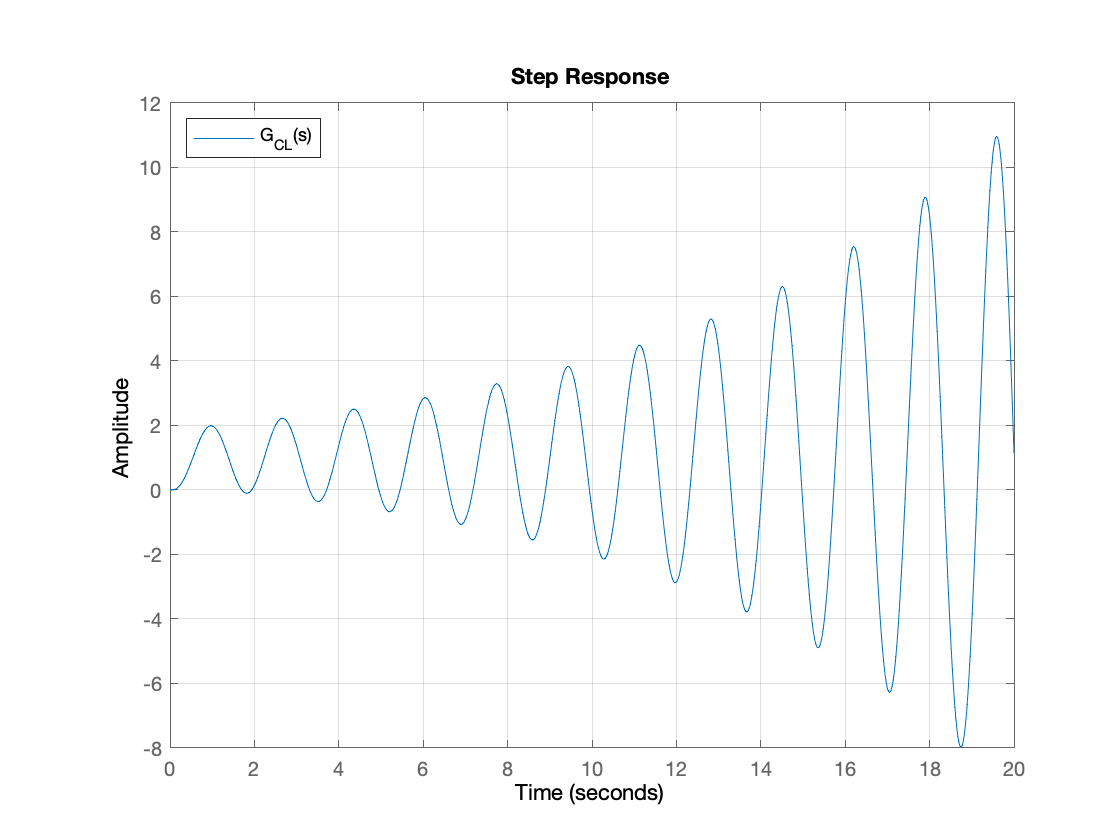

t=0:0.01:tfinal;
step(sys2,t);grid;legend('G_{CL}(s)','location','northwest');legend('G_{CL}(s)') % legend called twice to fix subscript bug